# **基于亮点模型的潜艇回波仿真**

***参考文献:***

***基于亮点模型的潜艇回波仿真  何心怡 蒋兴舟 林建域***

***一种基于亮点模型的潜艇回波仿真  董仲臣 ,李亚安,陈 晓***

clc;clear;close all;

## 1.仿真发射信号

信号的包络是一个梯形

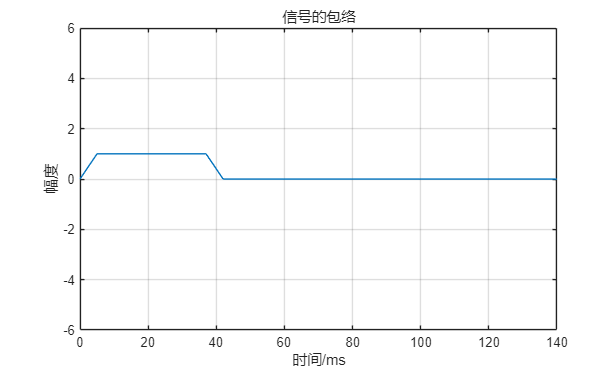

% 定义时间参数
fs = 30000;
t = 0:1/fs:0.14 - 1/fs; % 时间向量，这里生成0到0.14秒的时间序列，采样间隔为1/fs
Ts = 1/fs;
fc = 800;
c = 1500;
% 定义梯形脉冲参数
A = 1; % 幅度为1V
width = 32e-3; % 宽度为32ms
rise_time = 5e-3; % 上升时间设为5ms
fall_time = 5e-3; % 下降时间设为5ms

%入射角
theta = 180;


% 生成梯形脉冲
a = zeros(size(t));
for i = 1:length(t)
    if t(i) >= 0 && t(i) < rise_time
        a(i) = A * t(i) / rise_time;
    elseif t(i) >= rise_time && t(i) < rise_time + width
        a(i) = A;
    elseif t(i) >= rise_time + width && t(i) < rise_time + width + fall_time
        a(i) = A - A * (t(i) - (rise_time + width))/fall_time;
    end
end
% 绘制梯形脉冲信号
figure;
plot(t*1e3, a);
xlabel('时间/ms');ylabel('幅度');title('信号的包络');
grid on;
axis([0,140,-6,6]);

发射的窄带脉冲

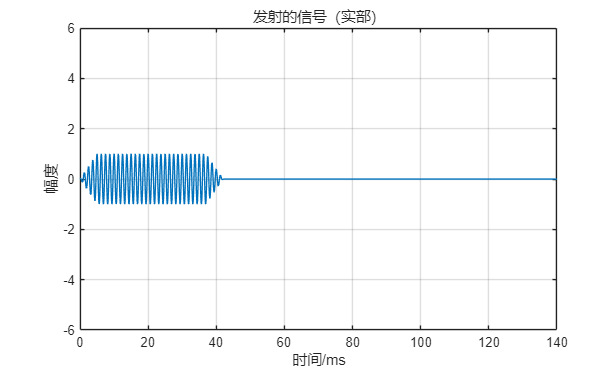

wc = 2*pi*fc;
P = a.*exp(j*wc*t);
figure;
plot(t*1e3, real(P));
xlabel('时间/ms');ylabel('幅度');title('发射的信号（实部）');
grid on;
axis([0,140,-6,6]);

## 2.多普勒频移

潜艇运动产生的多普勒频移：

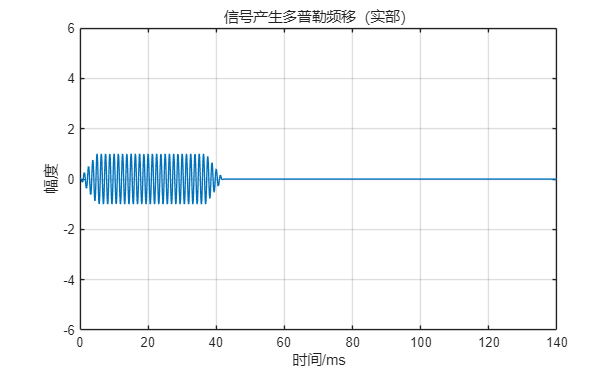

v = 4.116;%潜艇运动速度8海里/h
wd = 2*wc*v*cos(theta*pi/180)/c;%多普勒角频率

PWithDoplar = P.*exp(1j*wd*t);
figure;
plot(t*1e3, real(P));
xlabel('时间/ms');ylabel('幅度');title('信号产生多普勒频移（实部）');
grid on;
axis([0,140,-6,6]);

## 3.每个亮点的时延

R为鱼雷与潜艇距离,即鱼雷与代表艇尾的亮点距离;0为照射角;表示该亮点与艇艉的距离

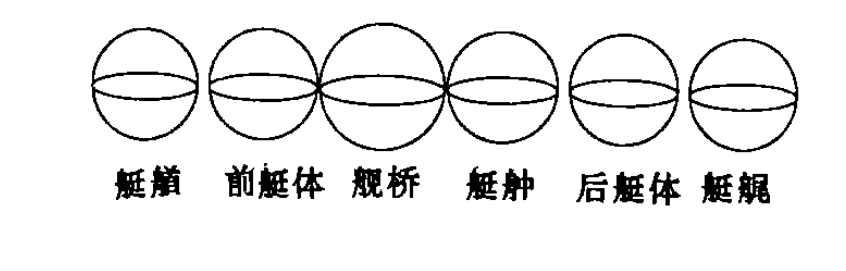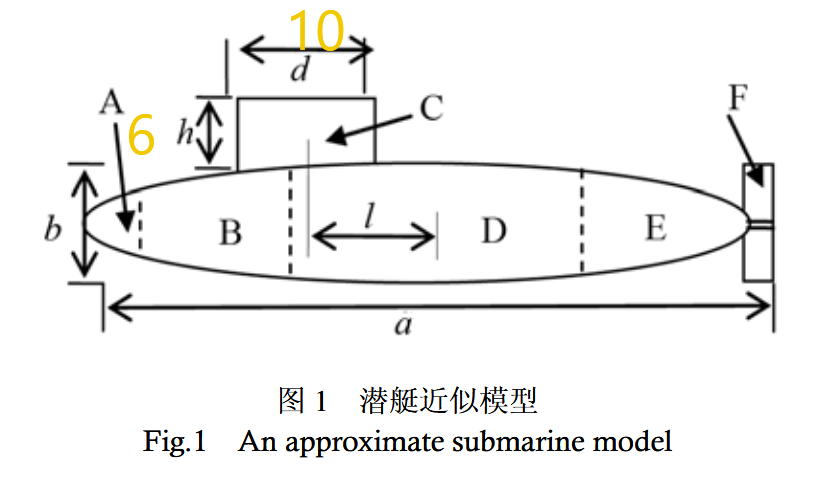

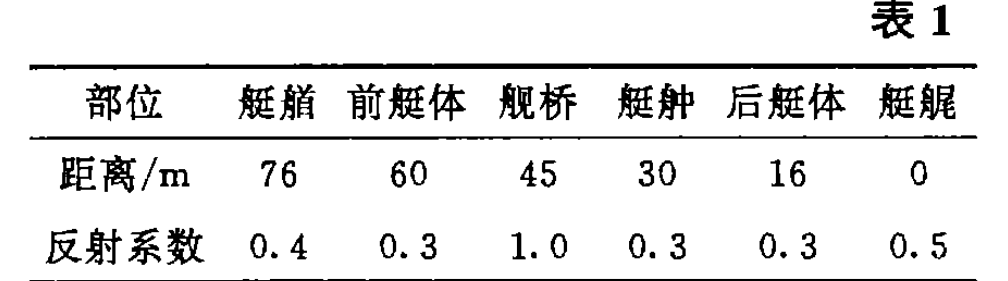

tau = zeros(6,length(theta));
L = zeros(6,1);  %L存放亮点与艇艇的距离
L = [76,  %A
     60,  %B
     45,  %C
     30,  %D
     16,  %E
     0];  %F
R = 1000;    %两者的距离
c = 1500;    %声速1500m/s
for i = 1:length(theta)
    for j = 1:6
        term1 = (R + L(j)*cos(theta(i)*pi/180)).^2;
        term2 = (L(j)*sin(theta(i)))^2;
        numerator = 2*sqrt(term1 + term2);
        tau(j,i) = numerator/c;
    end
end

## 4.计算亮点的子回波幅度

计算每个亮点的半径（这里数据不全）

% 定义距离和反射系数
L = [76, 60, 45, 30, 16, 0];
b = [0.4, 0.3, 1.0, 0.3, 0.3, 0.5];
r = [7,7,8,7,7,7];

### 计算隐蔽系数

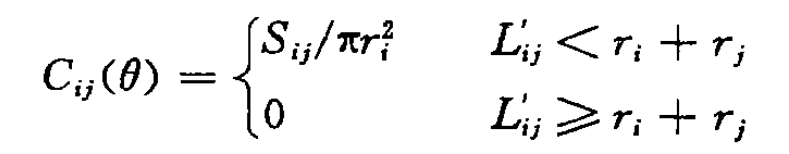

计算Sij

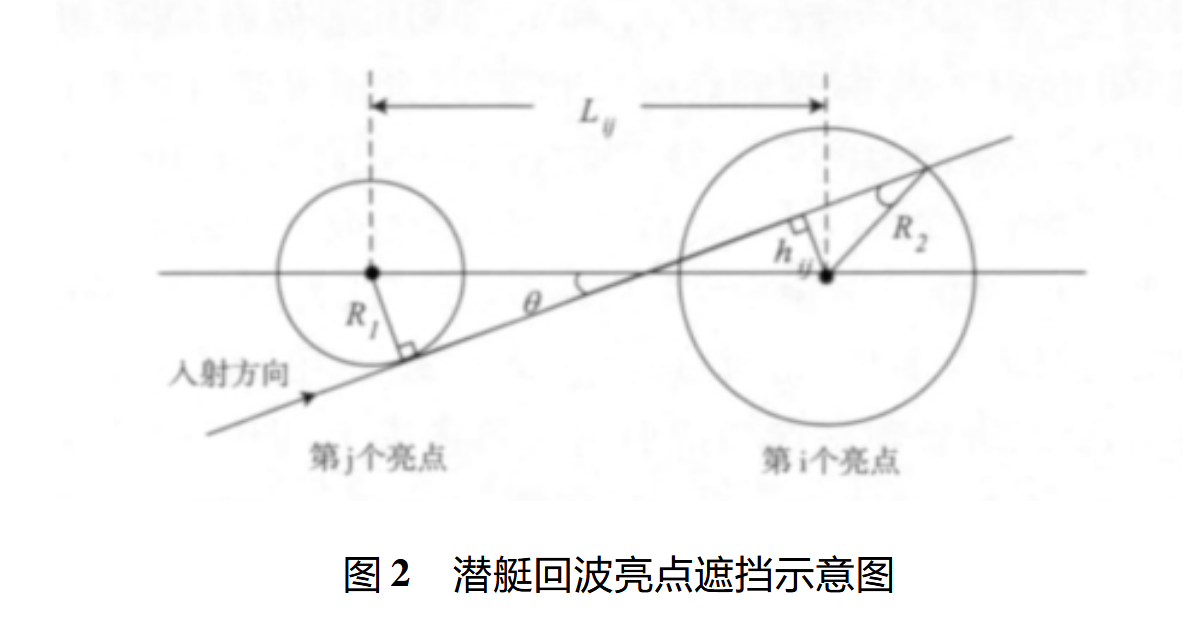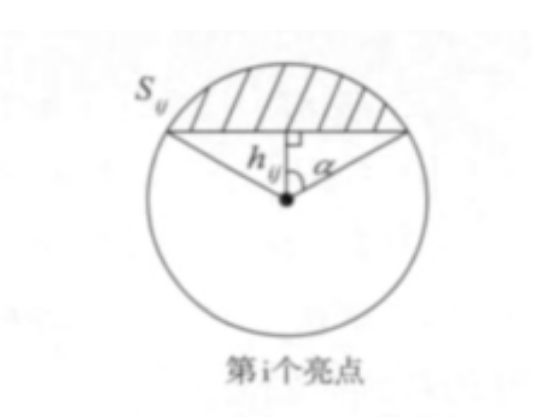

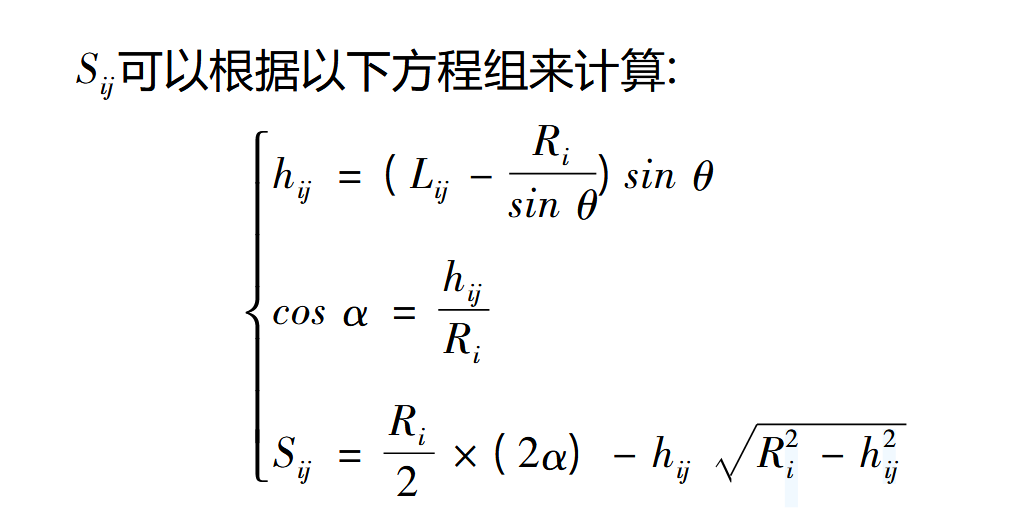

L_ij = zeros(6,6);
h_ji = zeros(6,6);
S_ij = zeros(6,6);

for i =1:6
    for j = 1:6
        L_ij(i,j) = L(j) - L(i);
        h_ij(i,j) = (L_ij(i,j) - r(i)./sin(theta*pi/180) ).*sin(theta*pi/180);
        alpha = acos(h_ij(i,j)/r(i));
        S_ij(i,j) = r(i)/2.*(2*alpha) - h_ij(i,j)*sqrt(r(i).^2 - h_ij(i,j).^2);

      %  C_ij(i,j) = S_ij(i,j)./(pi*r(i).^2);
    end
end


任何一个亮点最多可能被5个亮点所遮挡，最多也就有5个隐蔽系数,那么亮点i的隐蔽系数等于其中最大的隐蔽系数:

一个亮点的实际反射系数为

则一个亮点在考虑有隐蔽情况下其目标强度为

该亮点子回波的幅度为

% 计算隐蔽系数
C_ij = zeros(6,6);
for i = 1:6
    for j = 1:6
        if L(i) + L(j) < r(i) + r(j)
            C_ij(i, j) = S_ij(i,j)./(pi*r(i).^2); % 由于没有S_ij数据，这里设为0
        else
            C_ij(i, j) = 0;
        end
    end
end

% 计算每个亮点的实际反射系数
B = zeros(1, 6);
for i = 1:6
    C(i) = max(C_ij(i, :));
    B(i) = b(i) * (1 - C(i));
    % 计算目标强度
    TS(i) = 10 * log10(r(i).^2 / 4) + 10 * log10(B(i));
    
    % 计算亮点子回波幅度
    A(i) = 10.^(TS(i) / 20);
end




% 输出结果
disp(A);

    2.2136    1.9170    4.0000    1.9170    1.9170    2.2913



## 5.计算相位

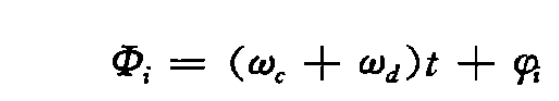

phi = pi;%假设相位跳变180°
Phi = (wc + wd).*t + phi;

## 6.计算回波

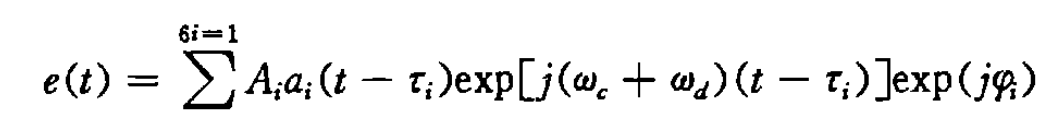

给包络加入时延：

disp(tau);

    1.2347
    1.2550
    1.2742
    1.2937
    1.3121
    1.3333



discDelay = round(tau./Ts);
disp(discDelay);

       37040
       37649
       38227
       38812
       39363
       40000




t = 0:1/fs:2 - 1/fs; % 时间向量，这里生成0到2秒的时间序列，采样间隔为1/fs
dotNum = length(a);
dotNumNew = length(t);

aWithDelay = zeros(6,length(t));
for i =1:6
    aWithDelay(i,:) = [zeros(1,discDelay(i)), a , zeros(1,dotNumNew-discDelay(i)-dotNum)];
end

载波加入时延：


PWithDoplarAndDelay = zeros(6,length(t));
for i =1:6
    PWithDoplarAndDelay(i,:) = [zeros(1,discDelay(i)), PWithDoplar , zeros(1,dotNumNew-discDelay(i)-dotNum)];
end

e = zeros(6,dotNumNew);
for i = 1:6
    e(i,:) = A(i).*aWithDelay(i,:).*PWithDoplarAndDelay(i,:).*exp(1j*phi);
end

各个部位亮点的回波：

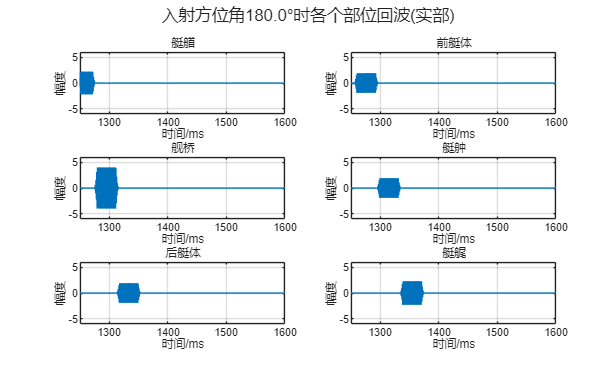

figure;

%艇艏亮点的回波：
subplot(3,2,1)
plot(t*1e3, real(e(1,:)));
xlabel('时间/ms');ylabel('幅度');title('艇艏');
grid on;
axis([1250,1600,-6,6]);
%前艇体
subplot(3,2,2)
plot(t*1e3, real(e(2,:)));
xlabel('时间/ms');ylabel('幅度');title('前艇体');
grid on;
axis([1250,1600,-6,6]);
%舰桥
subplot(3,2,3)
plot(t*1e3, real(e(3,:)));
xlabel('时间/ms');ylabel('幅度');title('舰桥');
grid on;
axis([1250,1600,-6,6]); 
% 艇舯 
subplot(3,2,4)
plot(t*1e3, real(e(4,:)));
xlabel('时间/ms');ylabel('幅度');title('艇舯');
grid on;
axis([1250,1600,-6,6]); 
% 后艇体
subplot(3,2,5)
plot(t*1e3, real(e(5,:)));
xlabel('时间/ms');ylabel('幅度');title('后艇体');
grid on;
axis([1250,1600,-6,6]); 
% 艇艉
subplot(3,2,6)
plot(t*1e3, real(e(6,:)));
xlabel('时间/ms');ylabel('幅度');title('艇艉');
grid on;
axis([1250,1600,-6,6]); 
sgtitle(sprintf('入射方位角%.1f°时各个部位回波(实部)', theta));

disp(r);

     7     7     8     7     7     7



整个舰体的回波

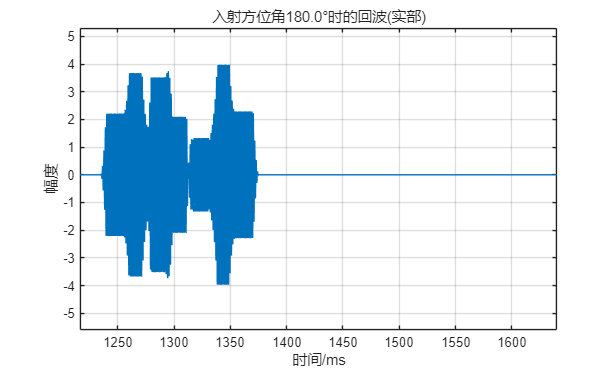

echo = sum(e,1);
figure;
%回波：
plot(t*1e3, real(echo));
xlabel('时间/ms');ylabel('幅度');title(sprintf('入射方位角%.1f°时的回波(实部)', theta));
grid on;
axis([1250,1600,-6,6]);

论文中的结果：

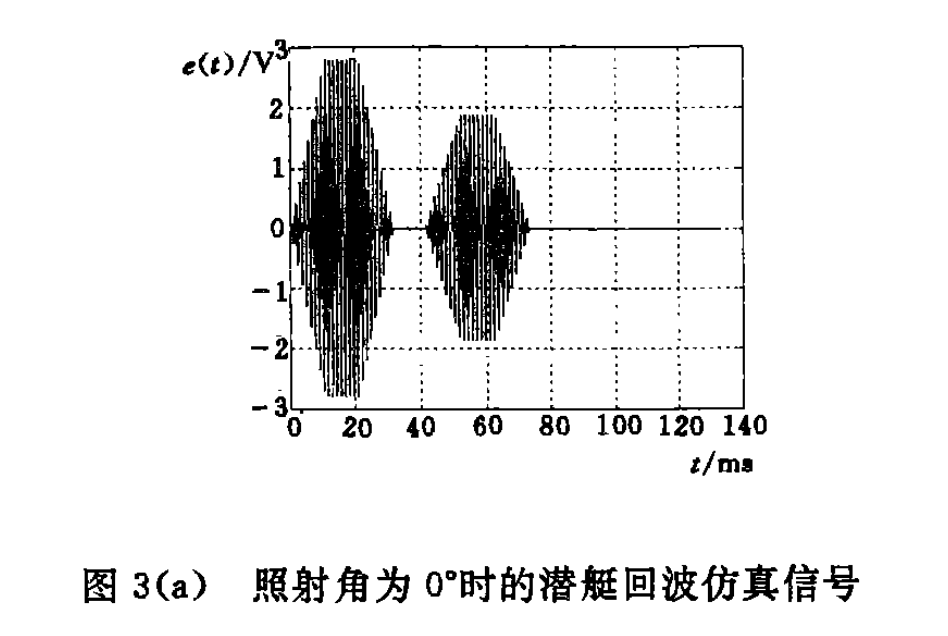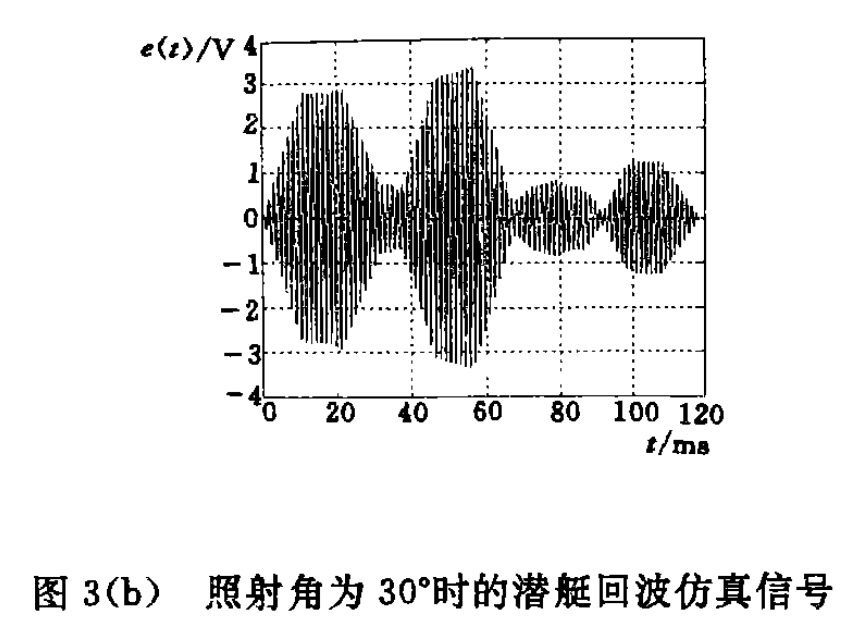

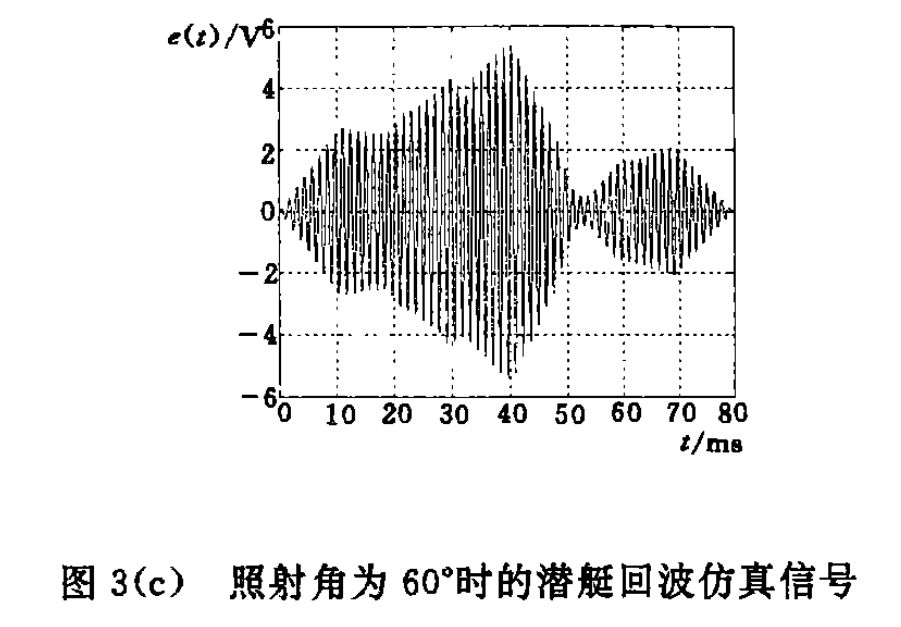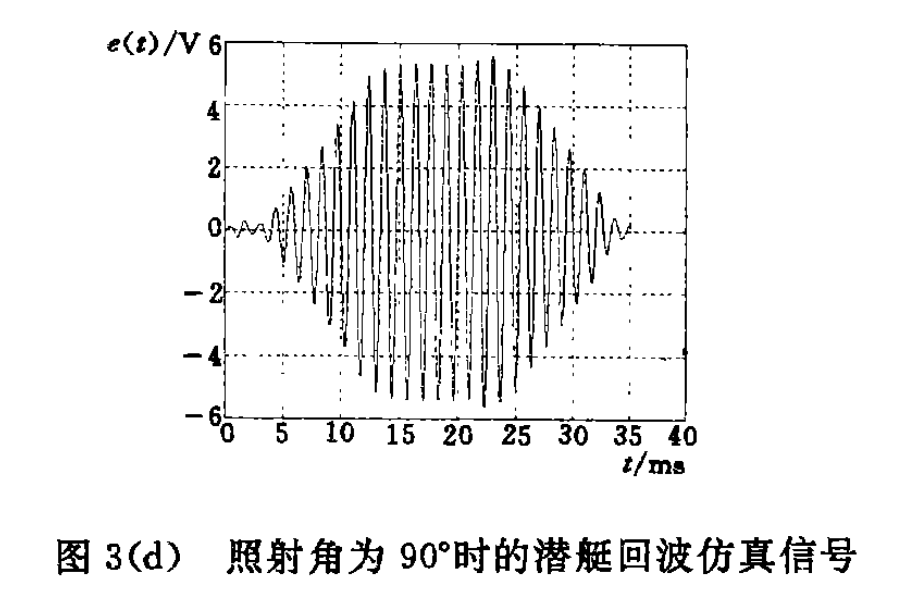

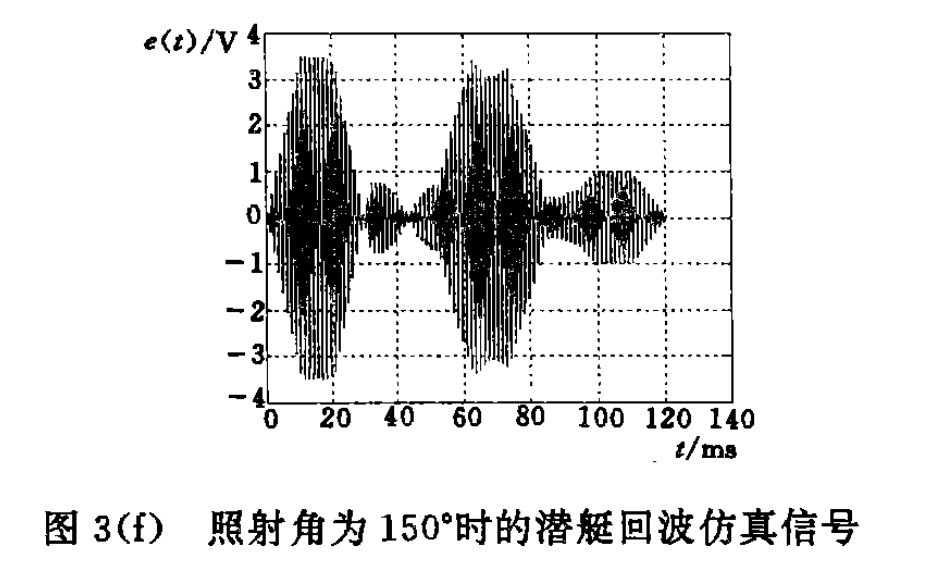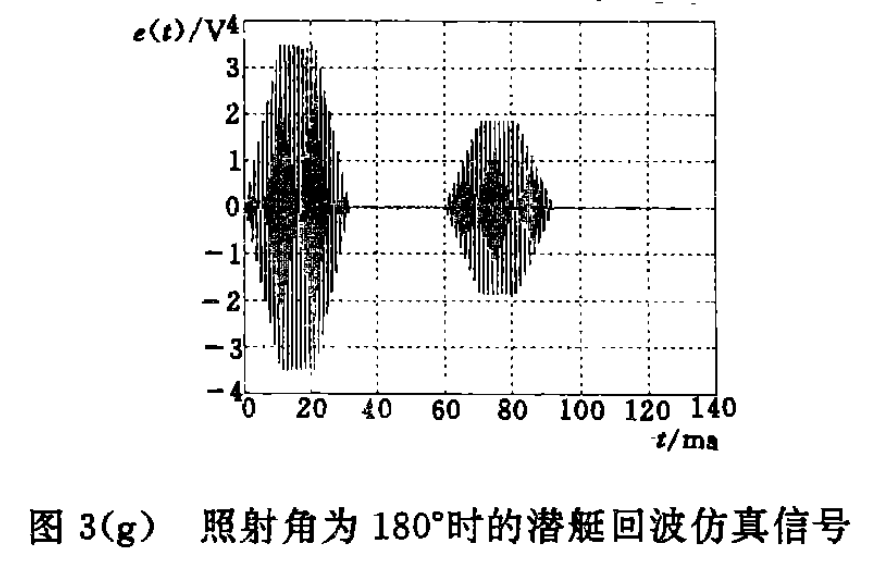

不一样的原因：载频不知道，

但是还是有问题，0°时应该只有两个亮点